%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% Simple example for comparison and evaluation of BOP-DMD
%
% Here we fit data generated from 3 
% spatial modes, each with time dynamics 
% which are exponential in time. 
%
% This example is used to compare between this reference code
% and the python version of this code.
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% ToDo:
% Loop of sigma
% Scatter plots of eigenvalues
% Alignment using match_vectors

clear all, close all, clc

## generate synthetic data

% set up modes in space

x0 = 0;
x1 = 1;
nx = 200;

% space

xspace = linspace(x0,x1,nx);

% modes

f1 = sin(xspace);
f2 = cos(xspace);
f3 = tanh(xspace);

% set up time dynamics

t0 = 0;
t1 = 1;
nt = 100;

ts = linspace(t0,t1,nt);

% eigenvalues

e_1 = 1;
e_2 = -2;
e_3 = 1i;

true_eigenvalues = [e_1;e_2;e_3];

% create clean dynamics

xclean = f1'*exp(e_1*ts) + f2'*exp(e_2*ts) + f3'*exp(e_3*ts);

% %corrupt results
% sam= 60;
% Atest2 = zeros(nx,length(ts));
% Arand1 = rand(nx,length(ts));
% Arand2 = rand(nx,length(ts));
% r1k = randperm(length(ts)*n,sam);
% 
% for j = 1:sam
%         Atest2(r1k(j))=1;
% end
% Anoise = Atest2.*(i*Arand1);
% Xnoise = xclean+Anoise;

## Run the BOP-DMD for varying levels of noise (sigma)

% Turn off the rank deficient warning as this triggers constantly
% for the noisiest data.
warning('off', 'MATLAB:rankDeficientMatrix')

% Set an array of varying levels of noise.
sigma_array = [0.1, 0.01, 0.001];

% Determine the number of points along the time dimension.
n = length(ts);

% Set the number of samples to use for each ensemble member.
p = 50;

% Determine the number of realizations of the noisy data.
num_Noisecycles = 25;

% Determine the number of ensemble members for each BOP-DMD solution.
num_cycles =  100;

% Initialize the matrices of eigenvalue solutions...

% ... for optDMD
lambda_vec_optDMD = zeros(3, num_Noisecycles, length(sigma_array));

% ... for BOP-DMD
lambda_vec_ensembleDMD = zeros(3, num_Noisecycles * num_cycles, length(sigma_array));

% Initialize the random seed
rand(1);

for sigma_ind = 1:length(sigma_array)
    fprintf('Sigma=%f\n', sigma_array(sigma_ind))
    for k = 1: num_Noisecycles
        fprintf('%i \n', k)

        % Create data for this realization of noisy data.
        xdata = xclean + sigma_array(sigma_ind) * randn(size(xclean));

        % Run the optdmd.
        [w_opt,e_opt,b_opt] = optdmd(xdata,ts,3,1,varpro_opts('ifprint',0));
        
        % Compare to actual eigenvalues
        indices = match_vectors(e_opt, true_eigenvalues);
        lambda_vec_optDMD(:, k, sigma_ind) = e_opt;
        
        for j = 1:num_cycles
                % Generate the ensemble members.
                unsorted_ind = randperm(n,p);
                % Sort to be in ascending order. NOTE that we now have a
                % variable delta t between members.
                ind = sort(unsorted_ind);
        
                % Create dataset for this cycle using the ensemble indices.
                xdata_cycle = xdata(:,ind);
                % Provide the index times.
                ts_ind = ts(ind);
        
                % Run the BOP-DMD with the optDMD modes as the initial conditions.
                [w_cycle,e_cycle,b_cycle] = optdmd(xdata_cycle,ts_ind,3,1,varpro_opts('ifprint',0),e_opt);

                % Compare to actual eigenvalues.
                indices = match_vectors(e_cycle, true_eigenvalues);
                lambda_vec_ensembleDMD(:, j * k, sigma_ind) = e_cycle(indices);
        end
    end
end

Sigma=0.100000


1 
2 
3 


4 
5 


6 
7 
8 
9 
10 
11 
12 
13 
14 
15 
16 
17 


18 
19 
20 


21 
22 
23 


24 
25 


Sigma=0.010000


1 
2 
3 
4 
5 
6 
7 
8 
9 
10 
11 
12 
13 
14 
15 
16 
17 
18 
19 
20 
21 
22 
23 
24 
25 


Sigma=0.001000


1 
2 
3 
4 
5 
6 
7 
8 
9 
10 
11 
12 
13 
14 
15 
16 
17 
18 
19 
20 
21 
22 
23 
24 
25 


sigma = 0.1000

fname = '../py_optDMD/examples/matlab_reference.BOP-DMD.sigma=0.1.png'

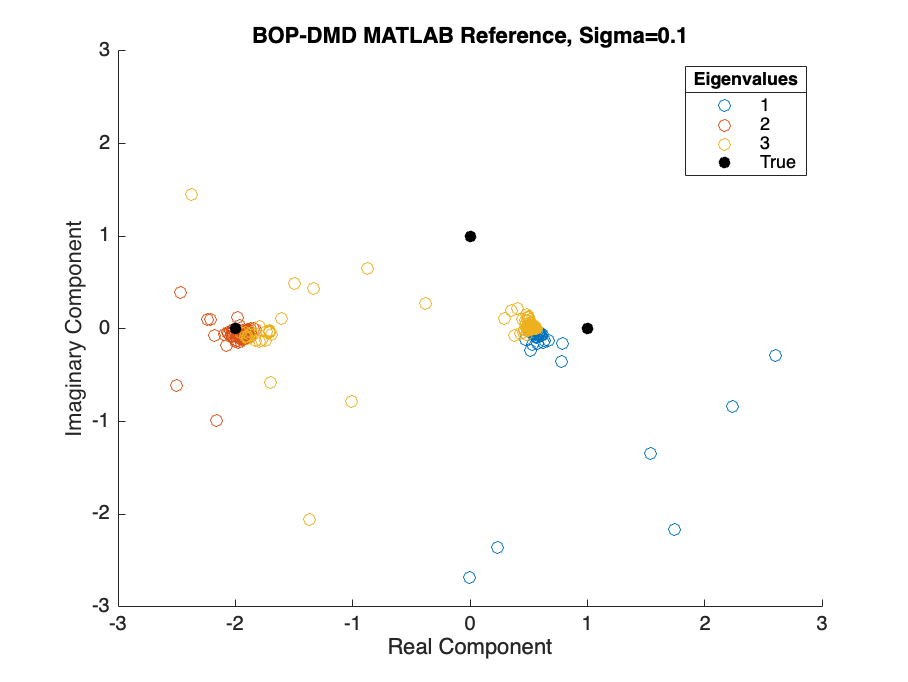

sigma = 0.0100

fname = '../py_optDMD/examples/matlab_reference.BOP-DMD.sigma=0.01.png'

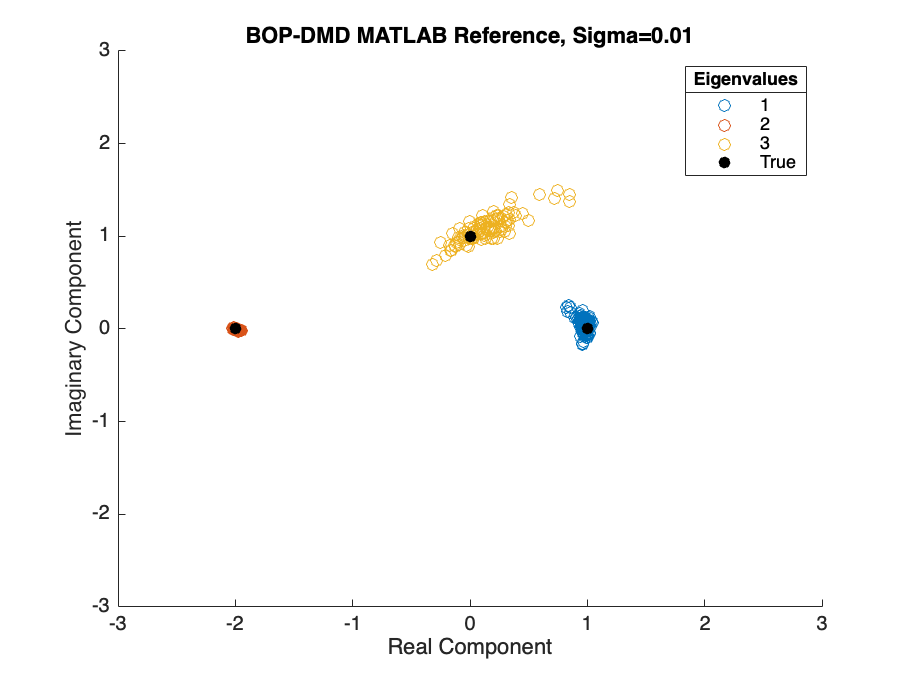

sigma = 1.0000e-03

fname = '../py_optDMD/examples/matlab_reference.BOP-DMD.sigma=0.001.png'

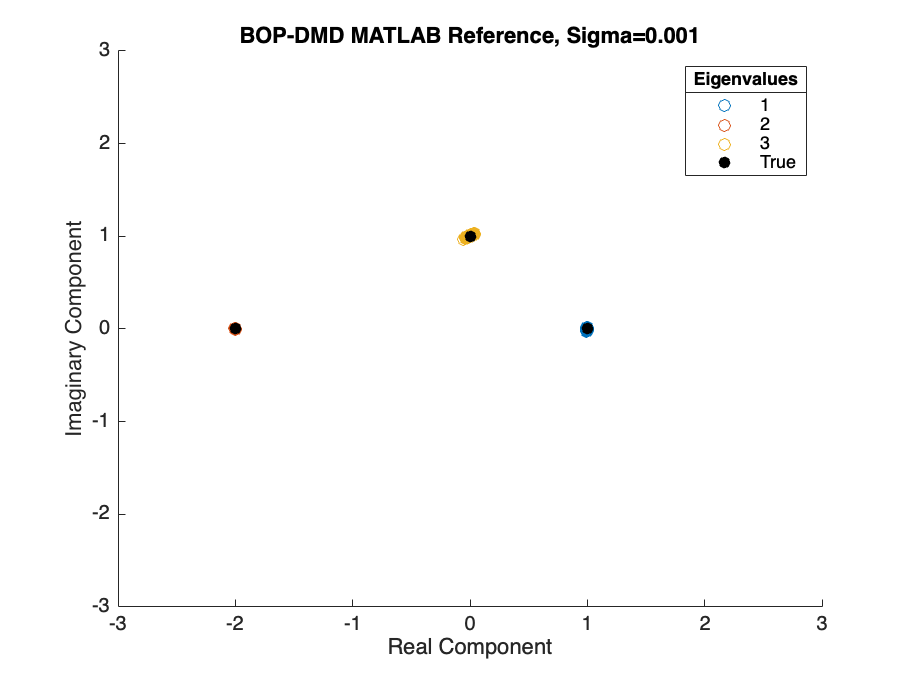

ans = '../py_optDMD/examples/matlab_reference.optDMD.sigma= .png'

for sigma_ind = 1:length(sigma_array)
    sigma = sigma_array(sigma_ind);
    figure()
    hold on
    for j = [1, 2, 3]
        scatter( ...
            real(lambda_vec_ensembleDMD(j, :, sigma_ind)), ...
            imag(lambda_vec_ensembleDMD(j, :, sigma_ind)) ...
            )
    end
    scatter(real(true_eigenvalues),imag(true_eigenvalues),'ko', 'filled')
    xlim([-3, 3])
    ylim([-3, 3])
    title(['BOP-DMD MATLAB Reference, Sigma=', num2str(sigma)])
    xlabel('Real Component')
    ylabel('Imaginary Component')
    lgd = legend('1', '2', '3', 'True');
    title(lgd, 'Eigenvalues')
    fname = ['../py_optDMD/examples/matlab_reference.BOP-DMD.sigma=', num2str(sigma), '.png'];
    saveas(gcf, fname);
end

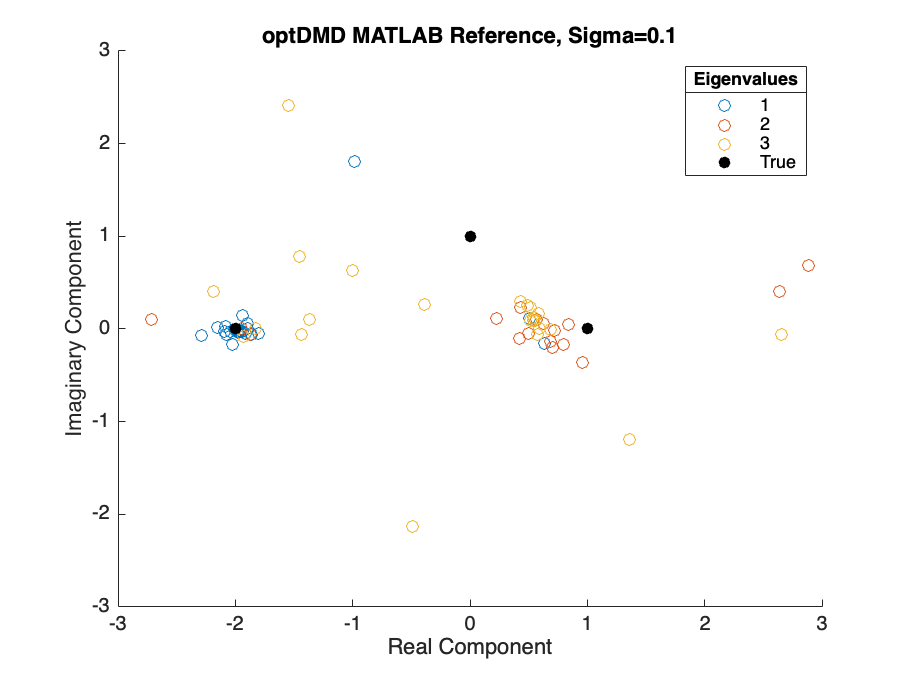

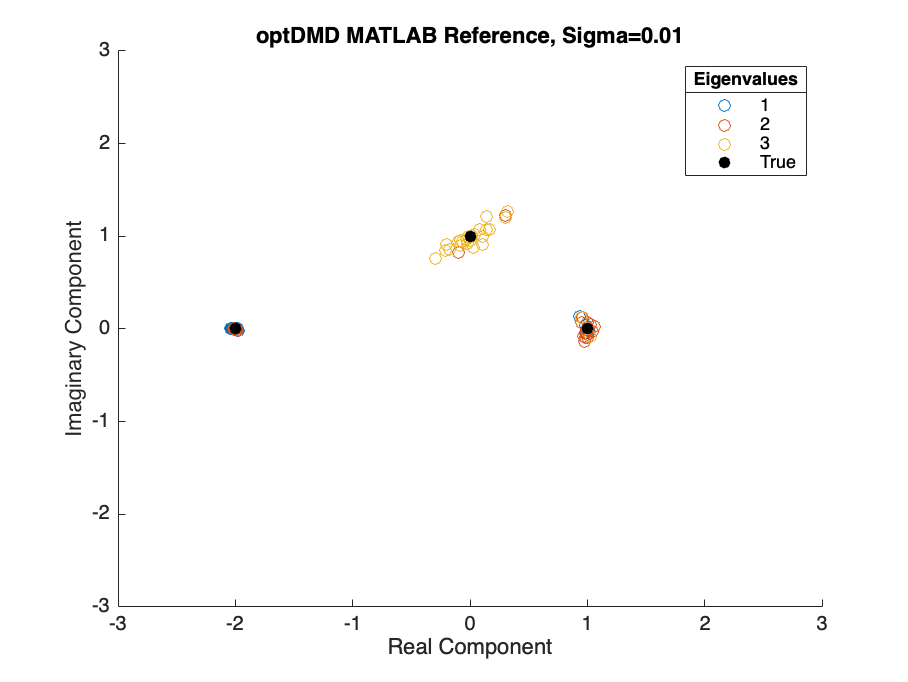

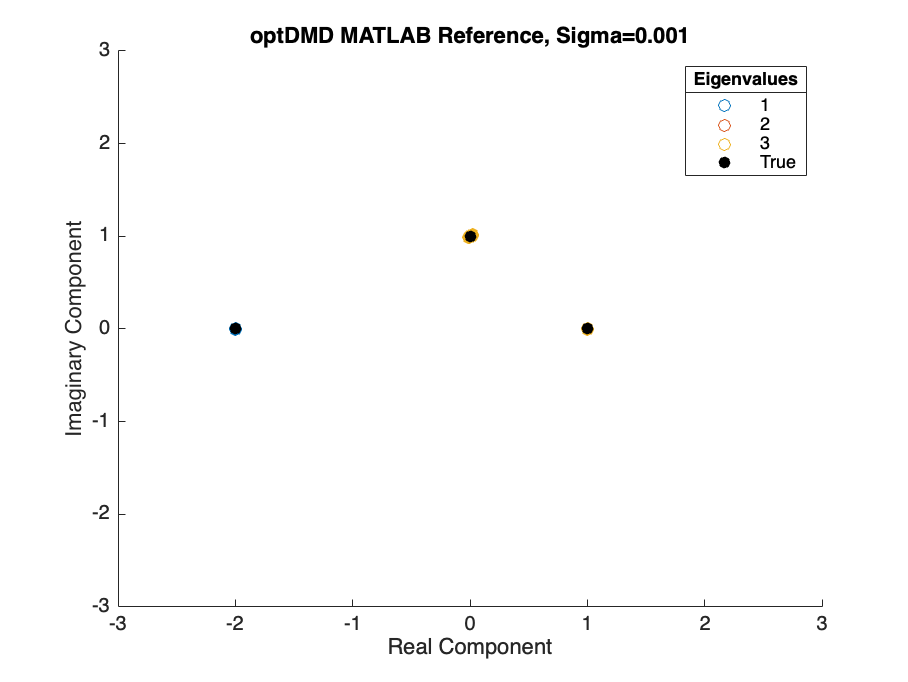

for sigma_ind = 1:length(sigma_array)
    figure()
    hold on
    for j = [1, 2, 3]
        scatter( ...
            real(lambda_vec_optDMD(j, :, sigma_ind)), ...
            imag(lambda_vec_optDMD(j, :, sigma_ind)) ...
            )
    end
    scatter(real(true_eigenvalues),imag(true_eigenvalues),'ko', 'filled')
    xlim([-3, 3])
    ylim([-3, 3])
    title(['optDMD MATLAB Reference, Sigma=', num2str(sigma_array(sigma_ind))])
    xlabel('Real Component')
    ylabel('Imaginary Component')
    lgd = legend('1', '2', '3', 'True');
    title(lgd, 'Eigenvalues')

    fname = ['../py_optDMD/examples/matlab_reference.optDMD.sigma=', num2str(sigma), '.png'];
    saveas(gcf, fname);

end